## Labs ABC branch analysis

We want to get some insights in branch output of lab results in 4 differents branches:

- Center

- North

- Industrial

- Express Service

First we need to clean the data. Since the Industrial branch works two shifts we need to divide their outputs by 2.

labs_abc_branches.industrial = labs_abc_branches.industrial ./ 2

labs_abc_branches = 195×7 table
    id       date        center    north    industrial    express_service                         notes                     
    __    ___________    ______    _____    __________    _______________    _______________________________________________

     1    01-Jan-2021     147       148         155              2           <undefined>                                    
     2    02-Jan-2021     166       150         155             16           <undefined>                                    
     3    03-Jan-2021     153       149         154             23           <undefined>                                    
     4    04-Jan-2021     157       152         155             45           <undefined>                

Then we need to remove the outliers, we'll use $\mu \pm \frac{3}{2}\sigma$

branches = table2array(labs_abc_branches(:, 3:6))

branches =   147.0000  148.0000  155.0000    2.0000
  166.0000  150.0000  155.0000   16.0000
  153.0000  149.0000  154.0000   23.0000
  157.0000  152.0000  155.0000   45.0000
  154.0000  149.0000  157.5000   15.0000
  153.0000  147.0000   70.0000    3.0000
  163.0000  153.0000  155.5000    6.0000
  161.0000  152.0000  155.0000    8.0000
  172.0000  151.0000  157.0000   29.0000
  158.0000  152.0000  155.5000   18.0000


avg = mean(branches)

avg =   158.8000  149.3846  142.7333   31.3026


std_dev = std(branches)

std_dev =    13.4105    7.0177   31.4056   28.4845


% calc top outliers limit
top = avg + 3/2 .* std_dev

top =   178.9157  159.9112  189.8418   74.0293


% calc bottom outliers limit
bottom = avg - 3/2 .* std_dev

bottom =   138.6843  138.8581   95.6249  -11.4242


center = branches(:, 1);
north = branches(:, 2);
industrial = branches(:, 3);
express = branches(:, 4);

center = center(center < top(1) & center > bottom(1));
north = north(north < top(2) & north > bottom(2));
industrial = industrial(industrial < top(3) & industrial > bottom(3));
express = express(express < top(4) & express > bottom(4));

now we can check the historgrams for each branch

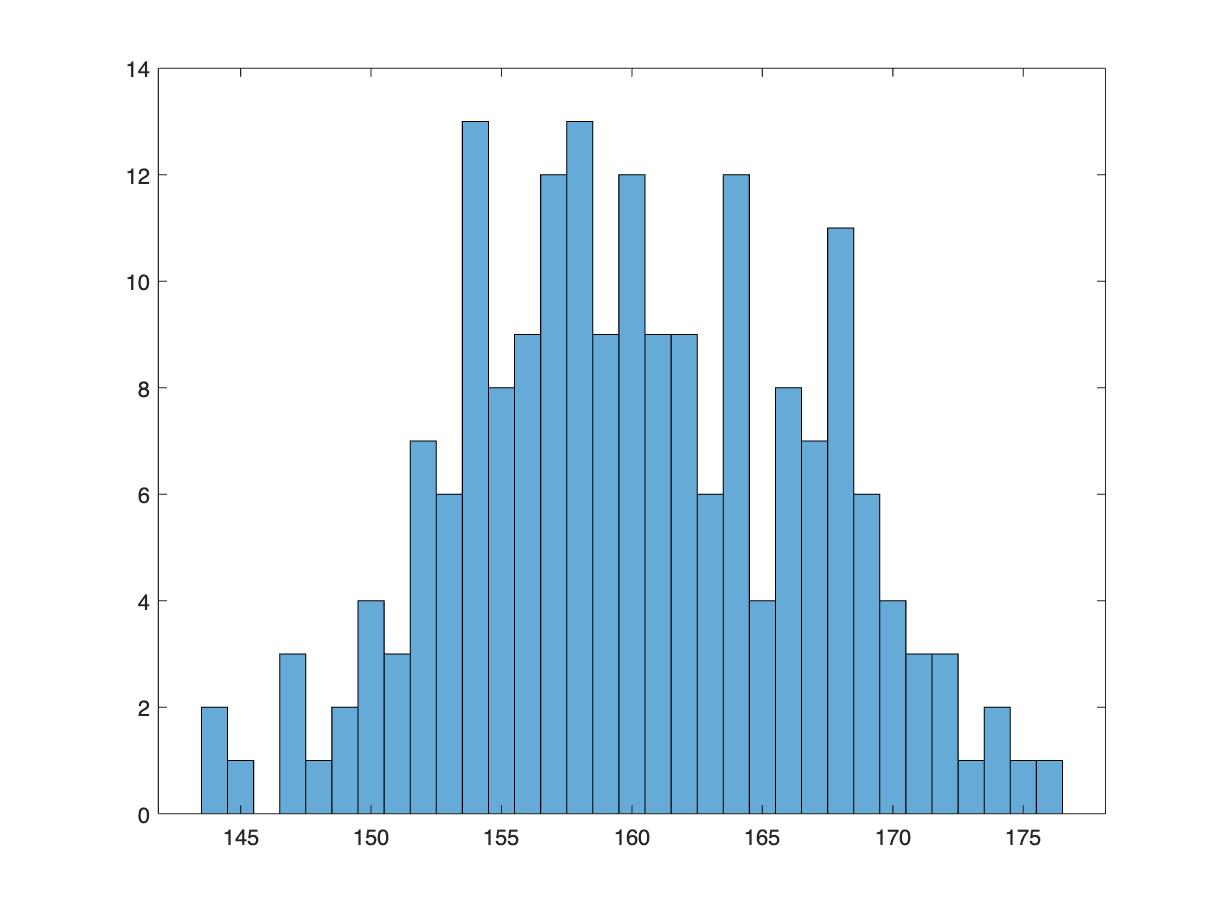

histogram(center)

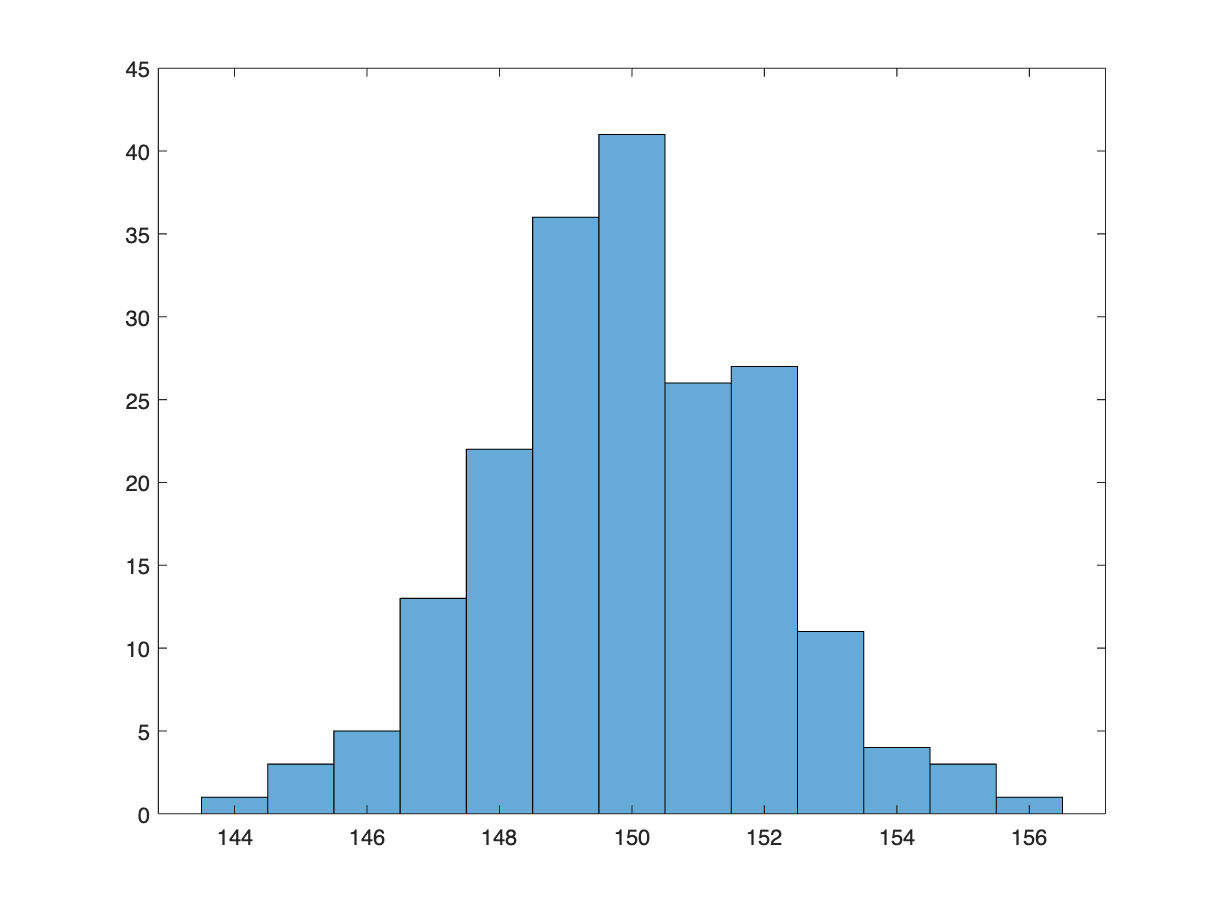

histogram(north)

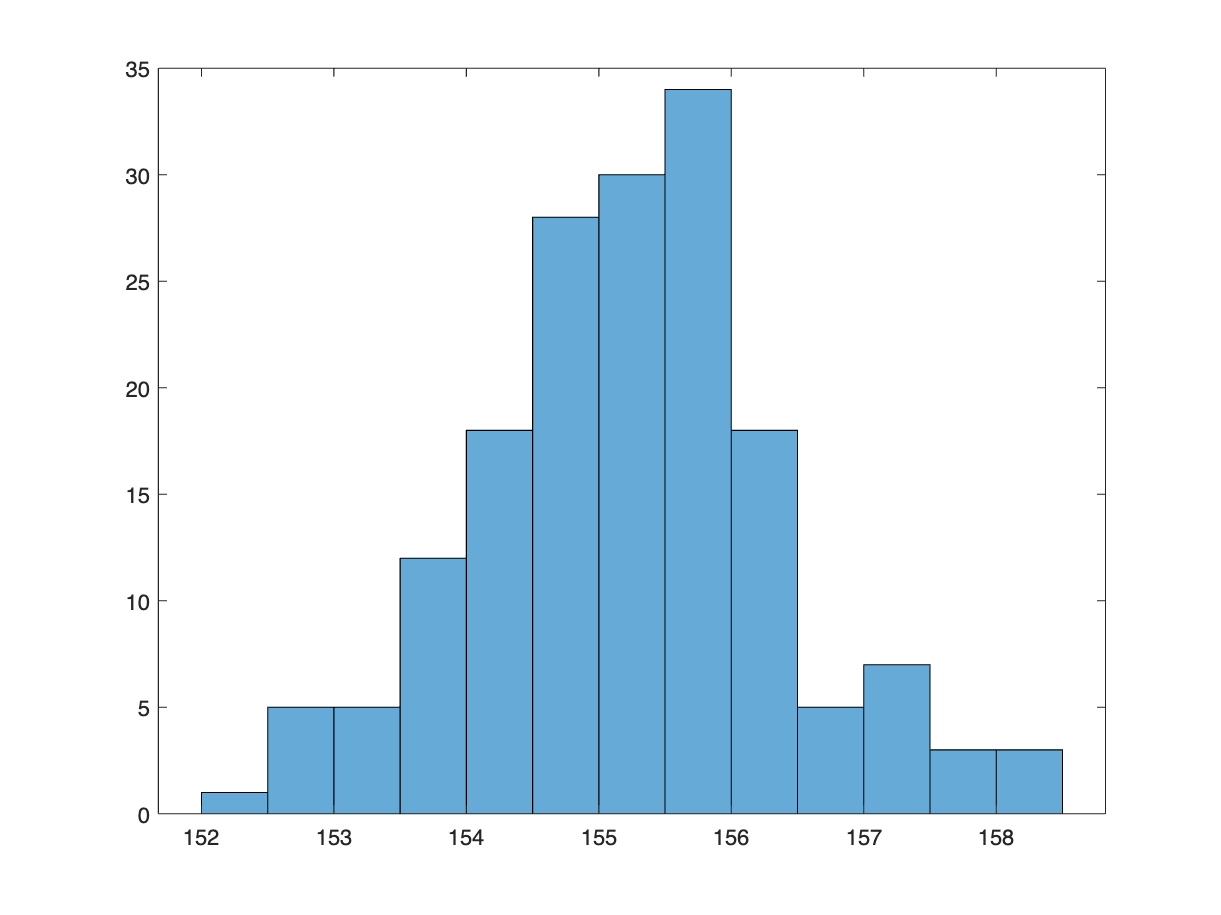

histogram(industrial)

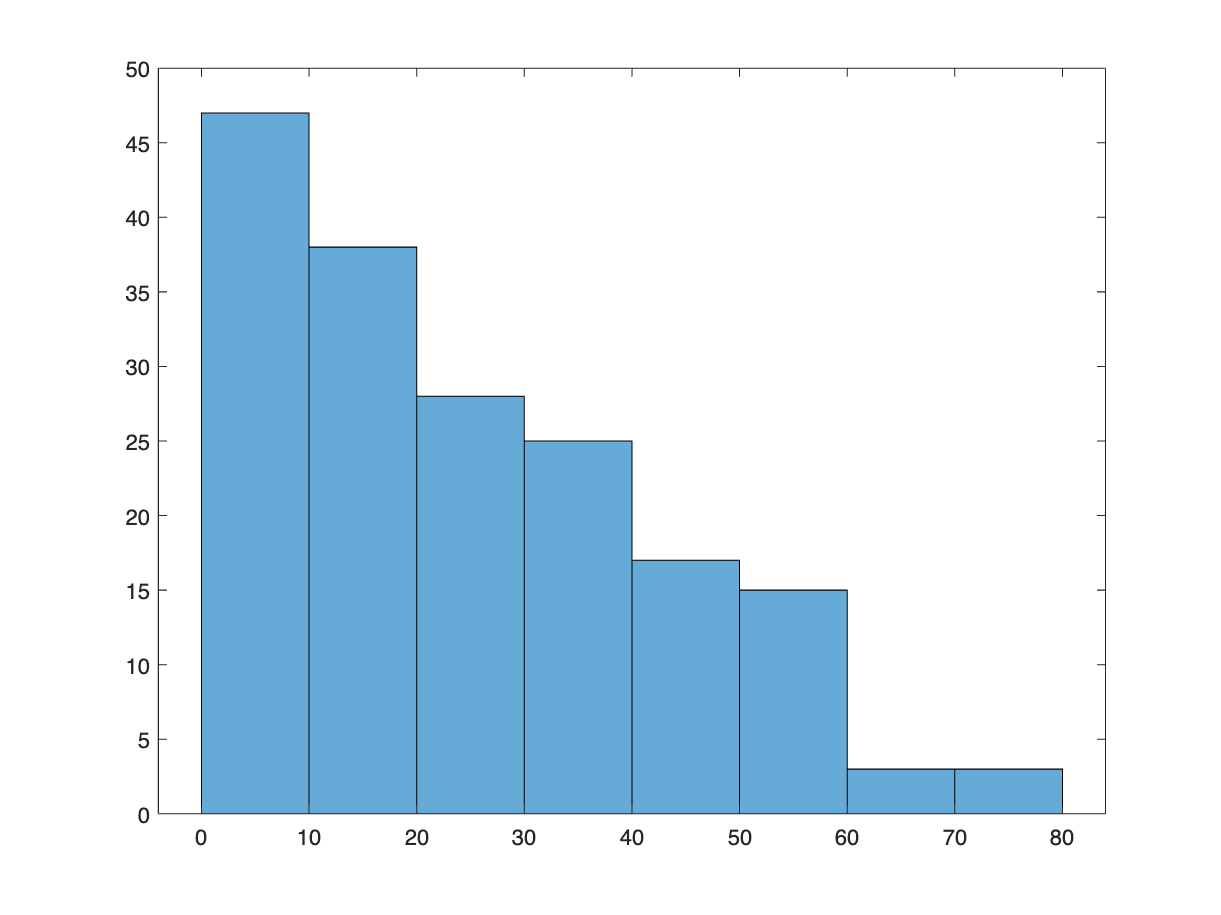

histogram(express)